mu_xi = 0

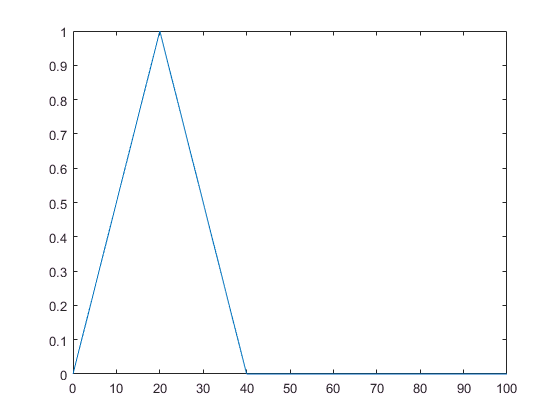

clc;clear;clear all;
global mu_xi;

altsinir_metreKare=0; ustsinir_metreKare=100;
altsinir_mevki=0; ustsinir_mevki=100;



%Giriþler
mKare_xi=88; mevki_xi=87; 

a1 = 0.1;         b1 = 0.1;          c1 = 0.24;
a2 = 0.34;        b2 = 0.39;         c2 = 0.59;
a3 = 0.41;        b3 = 0.47;         c3 = 0.63;
a4= .51;          b4= .55;           c4 = 1;
  
%Bulanik Kumelerin Olusturulmasi

%metre kare aðýrlýklý puaný
ucgen(altsinir_metreKare,0,20,40,ustsinir_metreKare,mKare_xi);  az_metreKare_xi=mu_xi;

mu_xi = 0

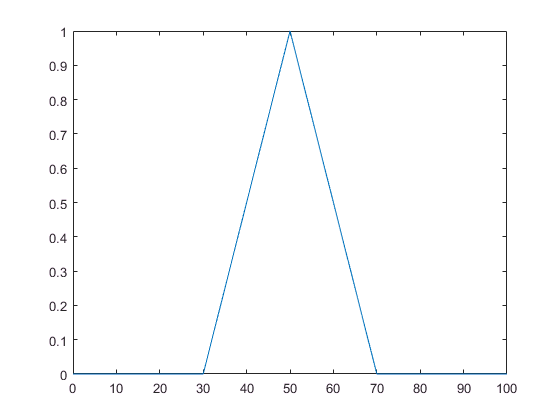

ucgen(altsinir_metreKare,30,50,70,ustsinir_metreKare,mKare_xi);  orta_metreKare_xi=mu_xi; 

mu_xi = 0.6000

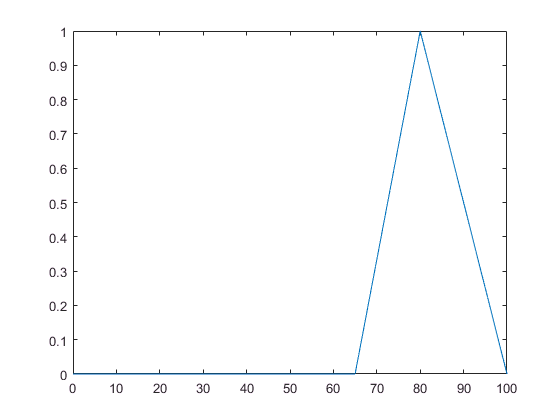

ucgen(altsinir_metreKare,65,80,100,ustsinir_metreKare,mKare_xi); cok_metreKare_xi=mu_xi;

mu_xi = 0


%mevki aðýrlýklý puaný
ucgen(altsinir_mevki,0,20,40,ustsinir_mevki, mevki_xi);  kotu_mevki_xi=mu_xi; 

mu_xi = 0

ucgen(altsinir_mevki,30,50,70,ustsinir_mevki, mevki_xi);  orta_mevki_xi=mu_xi; 

ucgen(altsinir_mevki,65,80,100,ustsinir_mevki, mevki_xi); iyi_mevki_xi=mu_xi; 

mu_xi = 0.6500

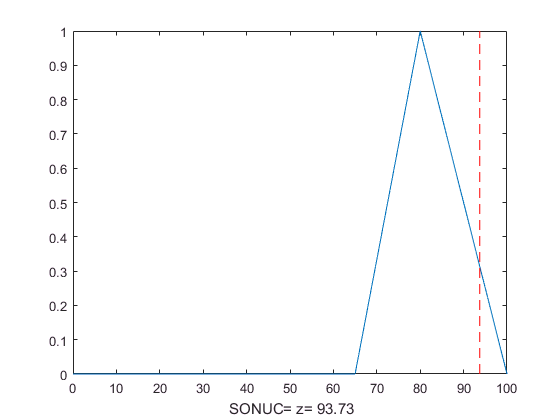



%  Cýkýþ Üyelik Fonksiyonu ev fiyati
z1 = a1*mKare_xi + b1*mevki_xi + c1;
z2 = a2*mKare_xi + b2*mevki_xi + c2;
z3 = a3*mKare_xi + b3*mevki_xi + c3;
z4 = a4*mKare_xi + b4*mevki_xi + c4;


%KURAL TABANI 
%VE Baðlacý olarak min operatörü kullanýlmýþtýr
w1 = min(az_metreKare_xi,kotu_mevki_xi);
w2 = min(az_metreKare_xi,orta_mevki_xi);
w3 = min(az_metreKare_xi,iyi_mevki_xi);

w4 = min(orta_metreKare_xi,kotu_mevki_xi);
w5 = min(orta_metreKare_xi,orta_mevki_xi);
w6 = min(orta_metreKare_xi,iyi_mevki_xi);

w7 = min(cok_metreKare_xi,kotu_mevki_xi);
w8 = min(cok_metreKare_xi,orta_mevki_xi);
w9 = min(cok_metreKare_xi,iyi_mevki_xi);


%Sonuçlarýn aðýrlýklý Toplamý Eþleþtirme Toplamý
SAT = w1*z1 + w2*z1 + w3*z2 + w4*z1 + w5*z2 + w6*z3 + w7*z2 + w8*z3 + w9*z4 ; 


%DURULAÞTIRMA operatörü olarak aðýrlýk merkezi kullanýlýyor
toplam_agirlik = w1 + w2 + w3 + w4 + w5 + w6 +w7+ w8 + w9;


z = SAT/toplam_agirlik;
h=[z z z z z z z z z z z];

line(h,0:0.1:1,'Color','red','LineStyle','--'); %durulaþtýrma sonucu

xlabel([' SONUC= z= ', num2str(z)]);